# Línea, Bola, Doble 03 - Generación de Datos

clear
clc
close all

% rng('shuffle');
rng('default');

load LBD_puntos

## Normalizar puntos polarmente

puntosBolasC = cell(1,Nejemplos);
puntosDoblesC = cell(1,Nejemplos);
puntosLineasC = cell(1,Nejemplos);

for i = 1:Nejemplos
    puntosBolasC{i}(:,1) = puntosBolas{i}(:,1)*pi/50; %argumento
    puntosBolasC{i}(:,2) = puntosBolas{i}(:,2)*0.5; % módulo

    puntosLineasC{i}(:,1) = puntosLineas{i}(:,1)*pi/50; %argumento
    puntosLineasC{i}(:,2) = puntosLineas{i}(:,2)*0.5; % módulo

    puntosDoblesC{i}(:,1) = puntosDobles{i}(:,1)*pi/50; %argumento
    puntosDoblesC{i}(:,2) = puntosDobles{i}(:,2)*0.5; % módulo
end


## Pasar puntos a Cartesianas reales

for i = 1:Nejemplos
    [puntosBolasC{i}(:,1), puntosBolasC{i}(:,2)] = pol2cart(puntosBolasC{i}(:,1), puntosBolasC{i}(:,2));
    [puntosLineasC{i}(:,1), puntosLineasC{i}(:,2)] = pol2cart(puntosLineasC{i}(:,1), puntosLineasC{i}(:,2));
    [puntosDoblesC{i}(:,1), puntosDoblesC{i}(:,2)] = pol2cart(puntosDoblesC{i}(:,1), puntosDoblesC{i}(:,2));
end

## Creación de imágenes

imagenesBolasC = cell(1,Nejemplos); 
imagenesLineasC = cell(1,Nejemplos); 
imagenesDoblesC = cell(1,Nejemplos); 

for i = 1:Nejemplos
    imagenesBolasC{i} = zeros(100,100);
    
    for j = 1:length(puntosBolasC{i})
        x = puntosBolasC{i}(j,1) + 50;
        y = puntosBolasC{i}(j,2) + 50;
        pos = ceil([100-y x]);
        
        imagenesBolasC{i}(pos(1),pos(2)) = imagenesBolasC{i}(pos(1),pos(2)) + 1;
    end
    
    imagenesBolasC{i} = rescale(imagenesBolasC{i});
end

for i = 1:Nejemplos
    imagenesLineasC{i} = zeros(100,100);
    
    for j = 1:length(puntosLineasC{i})
        x = puntosLineasC{i}(j,1) + 50;
        y = puntosLineasC{i}(j,2) + 50;
        pos = ceil([100-y x]);
        
        imagenesLineasC{i}(pos(1),pos(2)) = imagenesLineasC{i}(pos(1),pos(2)) + 1;
    end
    
    imagenesLineasC{i} = rescale(imagenesLineasC{i});
end

for i = 1:Nejemplos
    imagenesDoblesC{i} = zeros(100,100);
    
    for j = 1:length(puntosDoblesC{i})
        x = puntosDoblesC{i}(j,1) + 50;
        y = puntosDoblesC{i}(j,2) + 50;
        pos = ceil([100-y x]);
        
        imagenesDoblesC{i}(pos(1),pos(2)) = imagenesDoblesC{i}(pos(1),pos(2)) + 1;
    end
    
    imagenesDoblesC{i} = rescale(imagenesDoblesC{i});
end


## Dibujos

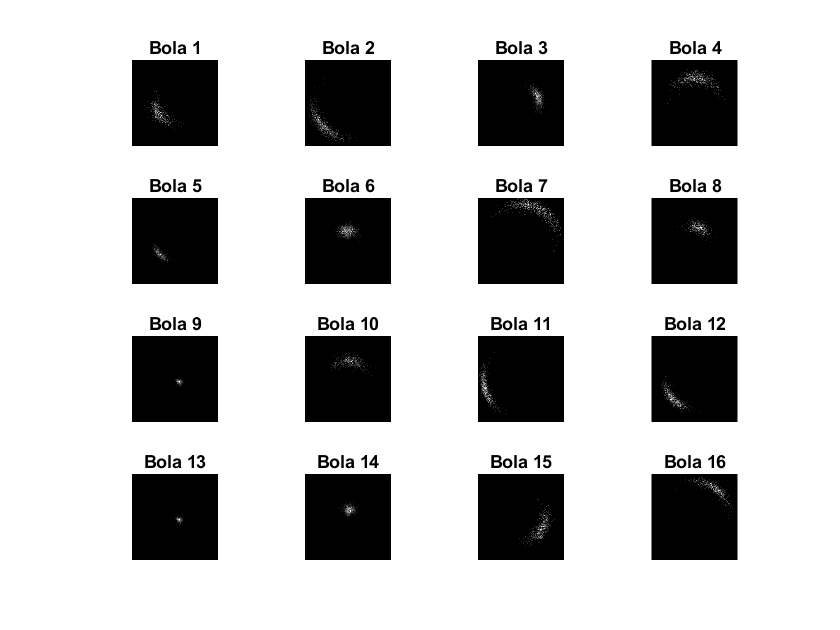

figure;
for i = 1:16
    subplot(4,4,i);
    imshow(imagenesBolasC{randi(100)});
    title(['Bola ', num2str(i)]);
end

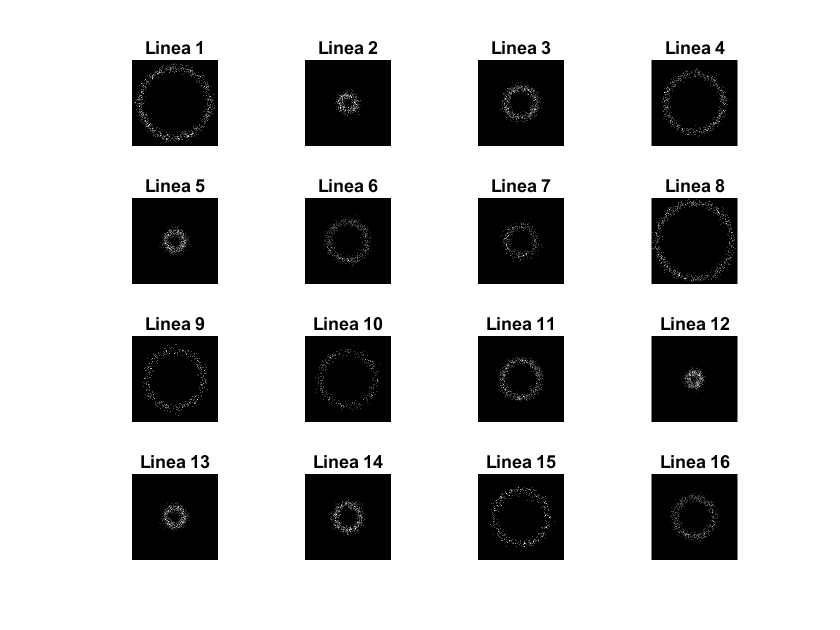

figure;
for i = 1:16
    subplot(4,4,i);
    imshow(imagenesLineasC{randi(100)});
    title(['Linea ', num2str(i)]);
end

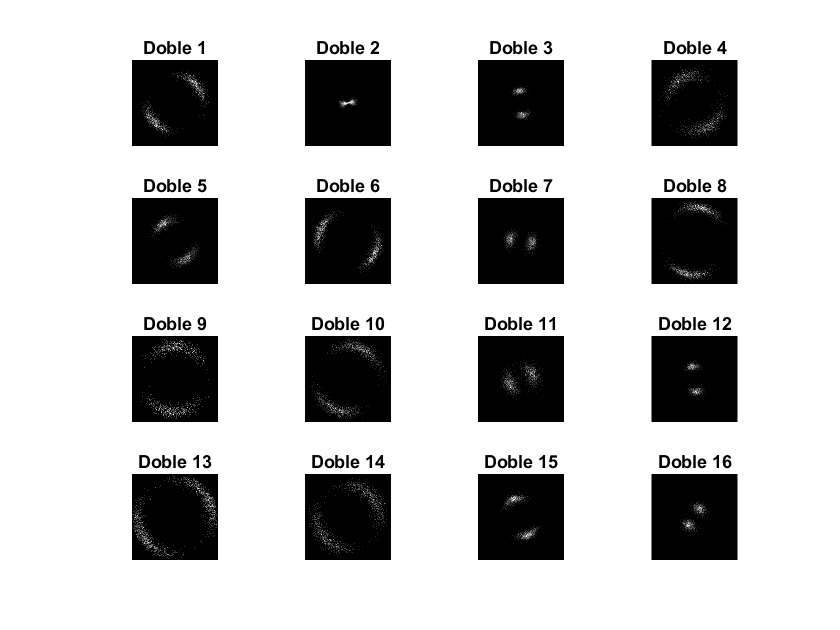

figure;
for i = 1:16
    subplot(4,4,i);
    imshow(imagenesDoblesC{randi(100)});
    title(['Doble ', num2str(i)]);
end

## Salvar imágenes para clasificación

for i = 1:Nejemplos
    img = imagenesBolasC{i};   
    str = strcat('.\imgLineaBolaDobleC\Bola\Bola_', num2str(i), '.png');
    imwrite(img, str);
end

for i = 1:Nejemplos
    img = imagenesLineasC{i};   
    str = strcat('.\imgLineaBolaDobleC\Linea\Linea_', num2str(i), '.png');
    imwrite(img, str);
end

for i = 1:Nejemplos
    img = imagenesDoblesC{i};   
    str = strcat('.\imgLineaBolaDobleC\Doble\Doble_', num2str(i), '.png');
    imwrite(img, str);
end

## Guardado de datos

save LBD_imgC imagenesBolasC imagenesLineasC imagenesDoblesC
save LBD_puntosC puntosBolasC puntosLineasC puntosDoblesC Nejemplos